# Capacity Factor Compare Places

Description: This algorithm plots the comparison of capacity factor and energy yield for the different places 

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek

Energy Geosystems Group -ANPERC - KAUST 11/2021

clc
clear
close all

% Make matrix  to plot the bars first collumn real data, 
% second from Global Solar Atlas
Caceres=[1950 1672];% Pedro
Thuwal=[1122 1845];% KAUST
Austin=[1268 1538];% Prof. Tad
M=[Thuwal;Caceres;Austin];%[kWh/kWp]

% Data from EIA from our analysis
EY=[0.199 0.167 0.148]*24*365;%[kWh/kWp]

## Figures

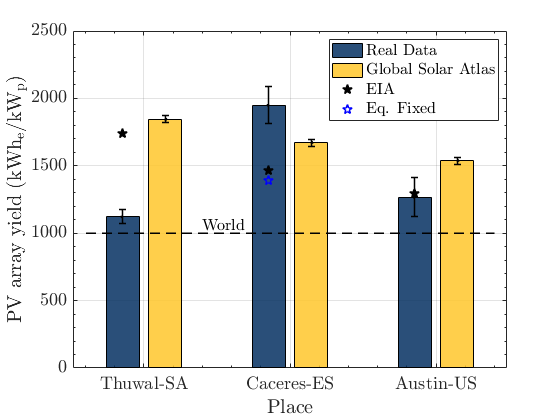

% Energy Yield
figure('Name','Energy Yield')
hold on
h=bar([1 1.5 2],M);
plot([0.925 1.425 1.925],EY,'p','Color',[0 0 0],'MarkerFaceColor',[0 0 0],'MarkerSize',10,'linewidth',1.5)
plot(1.425,1950/1.4,'pb','MarkerSize',10,'linewidth',1.5)
hold on
errorbar([0.925 1.075 1.425 1.575 1.925 2.075],[Thuwal,Caceres, Austin],[52 sqrt(Thuwal(2)*0.4) 135 sqrt(Caceres(2)*0.4) 147 sqrt(1538*0.4)],'.k','linewidth',1.5)
plot([0.8 2.2],[1000 1000],'--','color',[0 0 0],'LineWidth',1.5)
% Color
h(1).FaceColor = [5,48,97]/255;
h(1).FaceAlpha=0.85;
h(2).FaceAlpha=0.85;
h(2).FaceColor = [255,199,44]/255;
xlabel('$$\mathrm{Place}$$','interpreter','latex')
ylabel('PV array yield ($\mathrm{kWh_e/kW_p}$)','Interpreter','latex')
xticks([1 1.5 2])
xticklabels({'Thuwal-SA','Caceres-ES','Austin-US'})
legend('Real Data','Global Solar Atlas','EIA','Eq. Fixed','Interpreter','latex','FontSize',16)
text(1.2,1050,'World','Color',[0 0 0],'Interpreter','latex','FontSize',16)
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',18,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
 print('-dpng','-r400','CF_Exp_EY.png')

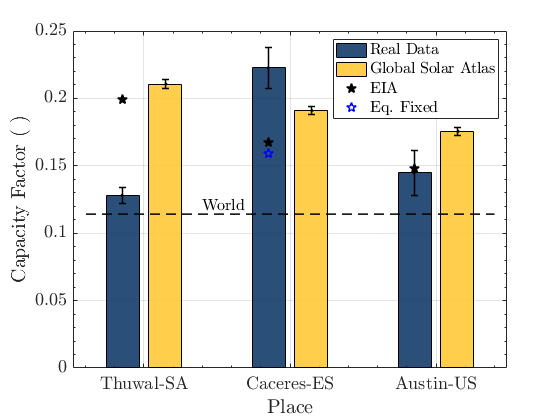

% Capacity Factor
% Converting factor from energy yield to capacity factor
fac=24*365;

figure('Name','Capacity Factor')
% plot(categorical(leg),nan)
hold on
h=bar([1 1.5 2],M/fac);
plot([0.925 1.425 1.925],EY/fac,'p','Color','k','MarkerFaceColor','k','MarkerSize',10,'linewidth',1.5)
plot(1.425,1950/1.4/fac,'pb','MarkerSize',10,'linewidth',1.5)
hold on
errorbar([0.925 1.075 1.425 1.575 1.925 2.075],[Thuwal,Caceres, Austin]/fac,[52 sqrt(Thuwal(2)*0.4) 135 sqrt(Caceres(2)*0.4) 147 sqrt(1538*0.4)]/fac,'.k','linewidth',1.5)
plot([0.8 2.2],[1000 1000]/fac,'--','color','k','LineWidth',1.5)
% Color
h(1).FaceColor = [5,48,97]/255;
h(1).FaceAlpha=0.85;
h(2).FaceAlpha=0.85;
h(2).FaceColor = [255,199,44]/255;
xlabel('$$\mathrm{Place}$$','interpreter','latex')
ylabel('Capacity Factor  ( )','Interpreter','latex')
xticks([1 1.5 2])
xticklabels({'Thuwal-SA','Caceres-ES','Austin-US'})
legend('Real Data','Global Solar Atlas','EIA','Eq. Fixed','Interpreter','latex','FontSize',15.5)
text(1.2,1050/fac,'World','Color','k','Interpreter','latex','FontSize',16)
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',18,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
print('-dpng','-r400','CF_Exp.png')